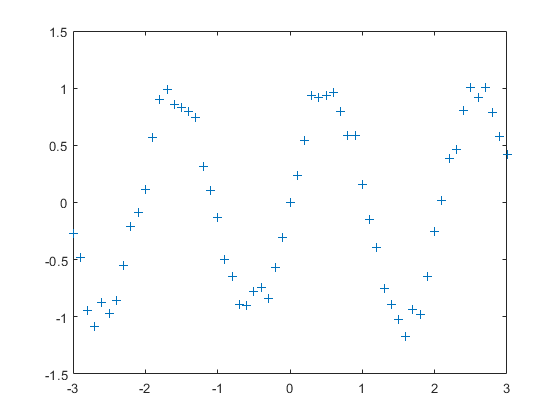

close all;
clear 
x = (-3:0.1:3).';                 % training inputs
y = sin(3*x) + 0.1*gpml_randn(0.9, length(x), 1);  % noisy training targets
xs = linspace(-3, 3, 61)';  % 61 test inputs

figure(1)
plot(x,y,'+')

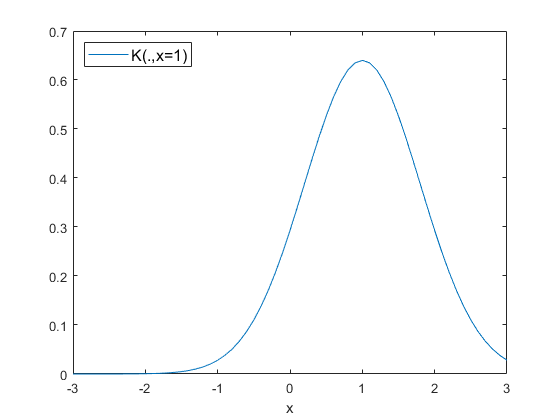

theta = [0.8;0.1;0.8];

n = length(y);
K = CovMatrix(x,theta(1),theta(3));
K_y = (K + theta(2)^2 * eye(n))^-1;

pos = 41; % hier ändern!!!

plot(x,K(pos,:))
legend('K(.,x=1)', 'Location','northwest','FontSize',12)
xlabel('x')

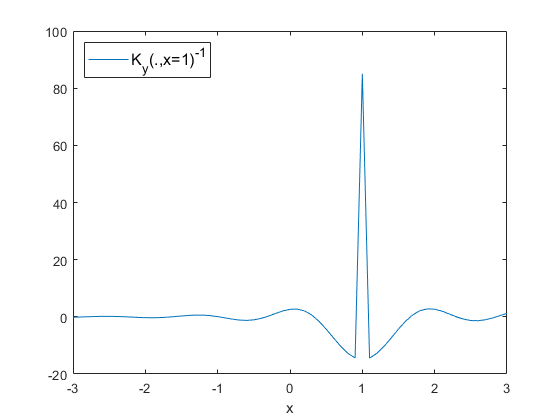


plot(x,K_y(pos,:))
legend('K_y(.,x=1)^{-1}', 'Location','northwest','FontSize',12)
xlabel('x')

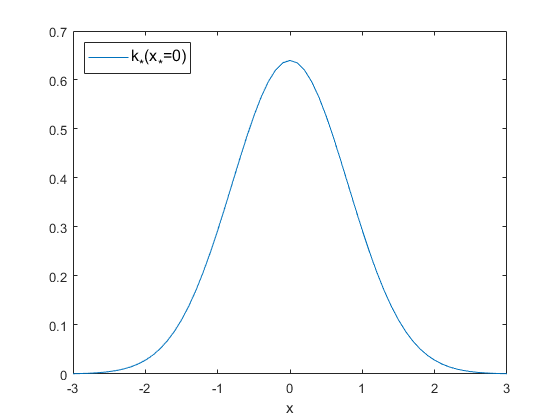

    posS = 31;
    ks = zeros(n,1);
    for i = 1 : n
         ks(i) = kernel(x(i),xs(posS),theta(1),theta(3)); 
    end
    
    plot(x,ks)
    xlabel('x')
    legend('k_*(x_*=0)', 'Location','northwest','FontSize',12)

    sum(ks)

ans = 12.8322

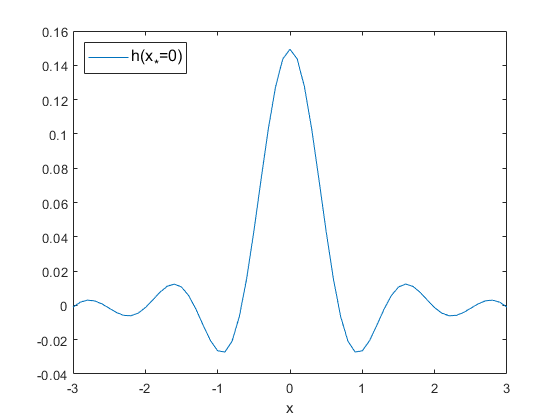

    
    h = ks.'*K_y;
    plot(x,h)
    xlabel('x')
    legend('h(x_*=0)', 'Location','northwest','FontSize',12)

    sum(h)

ans = 0.9999

    h*y

ans = 0.0094

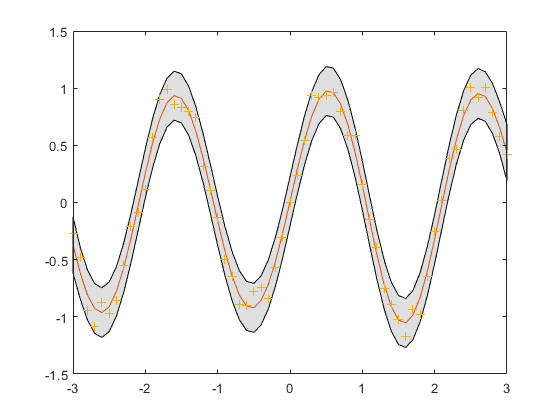

yPredict = zeros(length(xs),1);
sig = zeros(length(xs),1);

for i = 1: length(xs)
    [yPredict(i),sig(i)] = GPpredict_V1(K_y,x,y,xs(i),theta(1),theta(2),theta(3));
end
    sig = sig + theta(2)^2;

  f = [yPredict+2*sqrt(sig); flipdim(yPredict-2*sqrt(sig),1)];
  fill([xs; flipdim(xs,1)], f, [7 7 7]/8)
  hold on; 
  plot(xs, yPredict); 
  plot(x, y, '+')
  hold off;

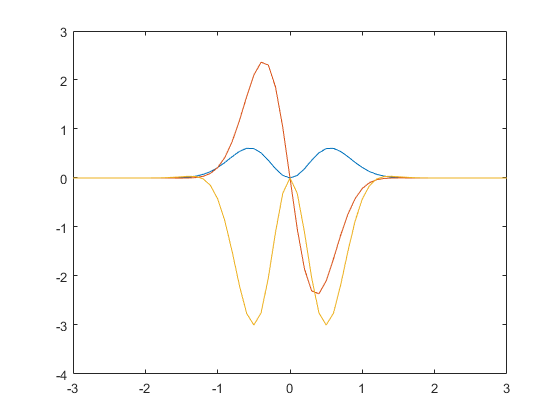

% Eigenwerte und Eigenvektoren
sigma = theta(1);
l = theta(3);

a = (4 * sigma^2)^-1;
b = (2*l^2)^-1;
c = sqrt((a^-1)^2+2*(a^-1 * b ^-1));
A = a^-1 + b^-1 + c^-1;
B = (b^-1)/A;

lambda1 = sqrt(2*a/A)*B;
lambda2 = sqrt(2*a/A)*B^2;
lambda3 = sqrt(2*a/A)*B^3;
phi = zeros(n,3);
for i = 1: n
    phi(i,1) = exp(-(c-a)*x(i)^2)* hermite1(x(i)) * (sqrt(2*c)*x(i));
    phi(i,2) = exp(-(c-a)*x(i)^2)* hermite2(x(i)) * (sqrt(2*c)*x(i));
    phi(i,3) = exp(-(c-a)*x(i)^2)* hermite3(x(i)) * (sqrt(2*c)*x(i));
end
%phiV = exp(-(c-a).*x.^2).* hermite(x,1) * (sqrt(2*c).*x);

plot(x, phi) 

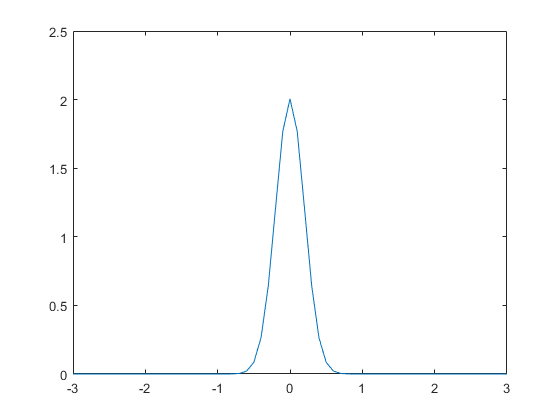

% Spektrum

s = x;
S = zeros(length(s),1);
for i = 1:1:length(s)
    S(i) = sqrt(2 * pi * l^2) * exp(-2*pi^2*l^2 *s(i)^2);
end

plot(s,S)

function h = hermite1(x)
    h = (-1)^1 * exp(x^2) * exp(-x^2)* (-2*x);
end

function h = hermite2(x)
    h = (-1)^2 * exp(x^2) * exp(-x^2)* (2*x^2-4);
end

function h = hermite3(x)
    h = (-1)^3 * exp(x^2) * exp(-x^2)* (-4*x*(2*x^2-3));
end

function h = hermite(data,k)
    n = length(data);
    h = zeros(n,1);
    syms x
    f = exp(-x^2);
    for i = 0 :1 : (k-1)
        f = diff(f);
    end
    
    for i = 1 : n
      h(i) = (-1)^k * exp(data(i)^2);% * f(data(i));  
    end
    

end